# **Generalized chi-square distribution** · Getting started

The generalized chi-square variable is a quadratic form of a normal variable, or equivalently, a linear sum of independent non-central chi-square variables and a normal variable.

For function features and documentation, type:

doc gx2_to_norm_quad_params
doc norm_quad_to_gx2_params
doc gx2stat
doc gx2rnd
doc gx2char
doc gx2cdf
doc gx2pdf
doc gx2inv

Abhranil Das

Center for Perceptual Systems, University of Texas at Austin

Comments, questions, bugs to abhranil.das@utexas.edu

If you use this toolbox, please cite:

- [A method to integrate and classify normal distributions](https://arxiv.org/abs/2012.14331).

- [New methods for computing the generalized chi-square distribution.](https://arxiv.org/abs/2404.05062)

## Calculate mean and variance

% gx2 parameters
w=[1 -10 2];
k=[1 2 3];
lambda=[2 3 7];
s=5;
m=10;

[mu,v]=gx2stat(w,k,lambda,s,m)

mu =    -17


v =         1771


## Generate random samples

r=gx2rnd(w,k,lambda,s,m,[1 1e5]);

## Calculate pdf and cdf

x=[10 25];
f=gx2pdf(x,w,k,lambda,s,m)

f =    0.012057086510927   0.008798029700009


p=gx2cdf(x,w,k,lambda,s,m)

p =    0.714979825628127   0.878998656902299


### Calculate cdf and pdf with different methods

x=linspace(-200,100,50);
p_ifft=gx2cdf(x,w,k,lambda,s,m,'method','ifft');
p_imhof=gx2cdf(x,w,k,lambda,s,m,'method','imhof');
p_ray=gx2cdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e4);

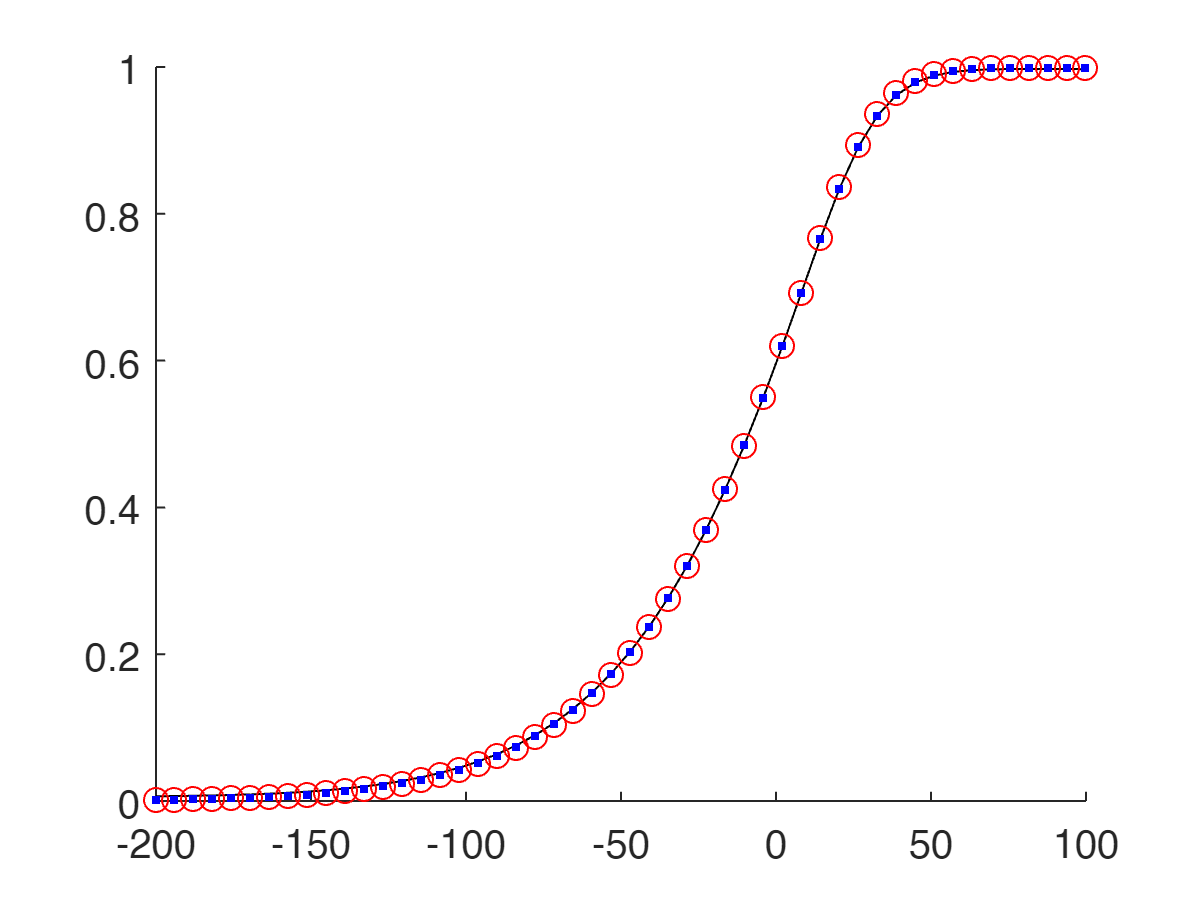

figure; hold on
plot(x,p_ifft,'-k')
plot(x,p_imhof,'.b')
plot(x,p_ray,'or')

f_ifft=gx2pdf(x,w,k,lambda,s,m,'method','ifft');
f_imhof=gx2pdf(x,w,k,lambda,s,m,'method','imhof');
f_ray=gx2pdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e6);

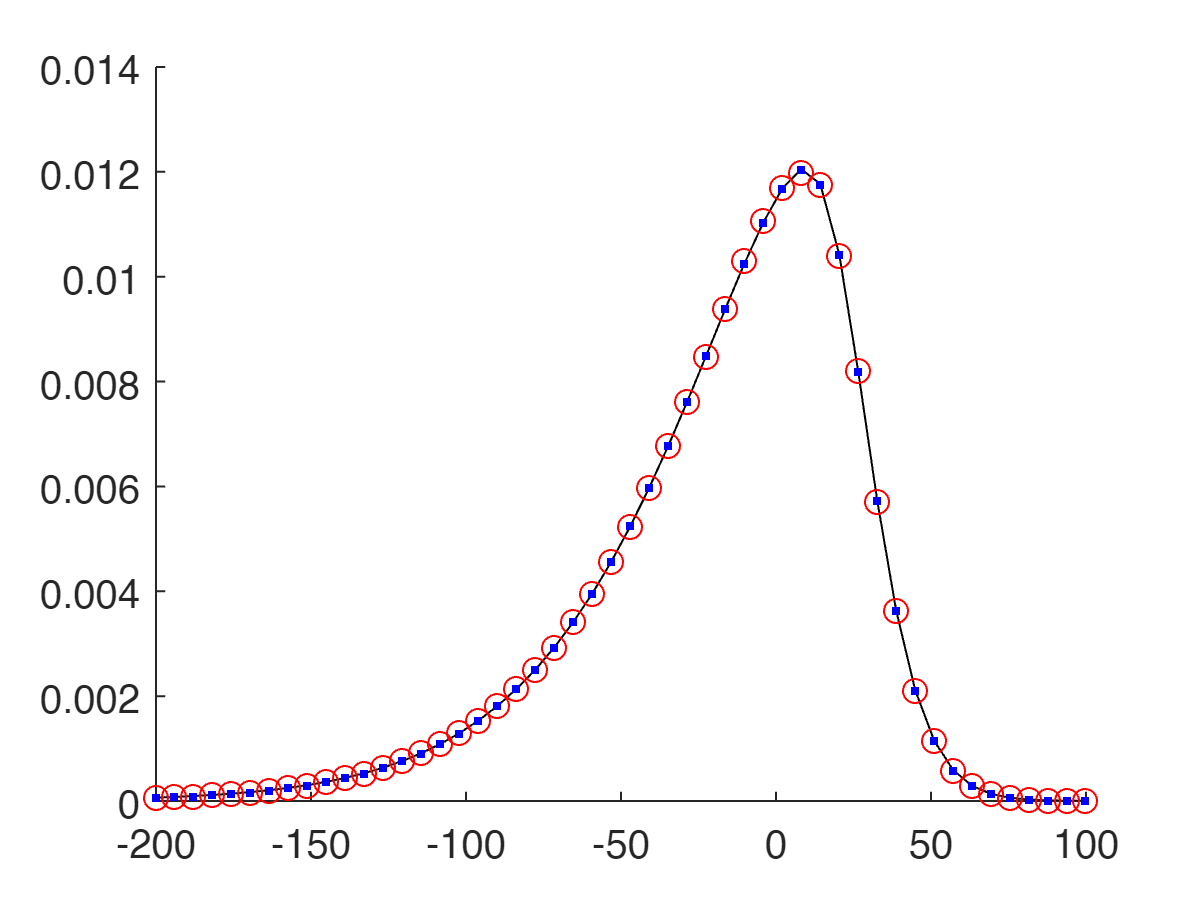


figure; hold on
plot(x,f_ifft,'-k')
plot(x,f_imhof,'.b')
plot(x,f_ray,'or')

### Compare calculated and sampled pdf's

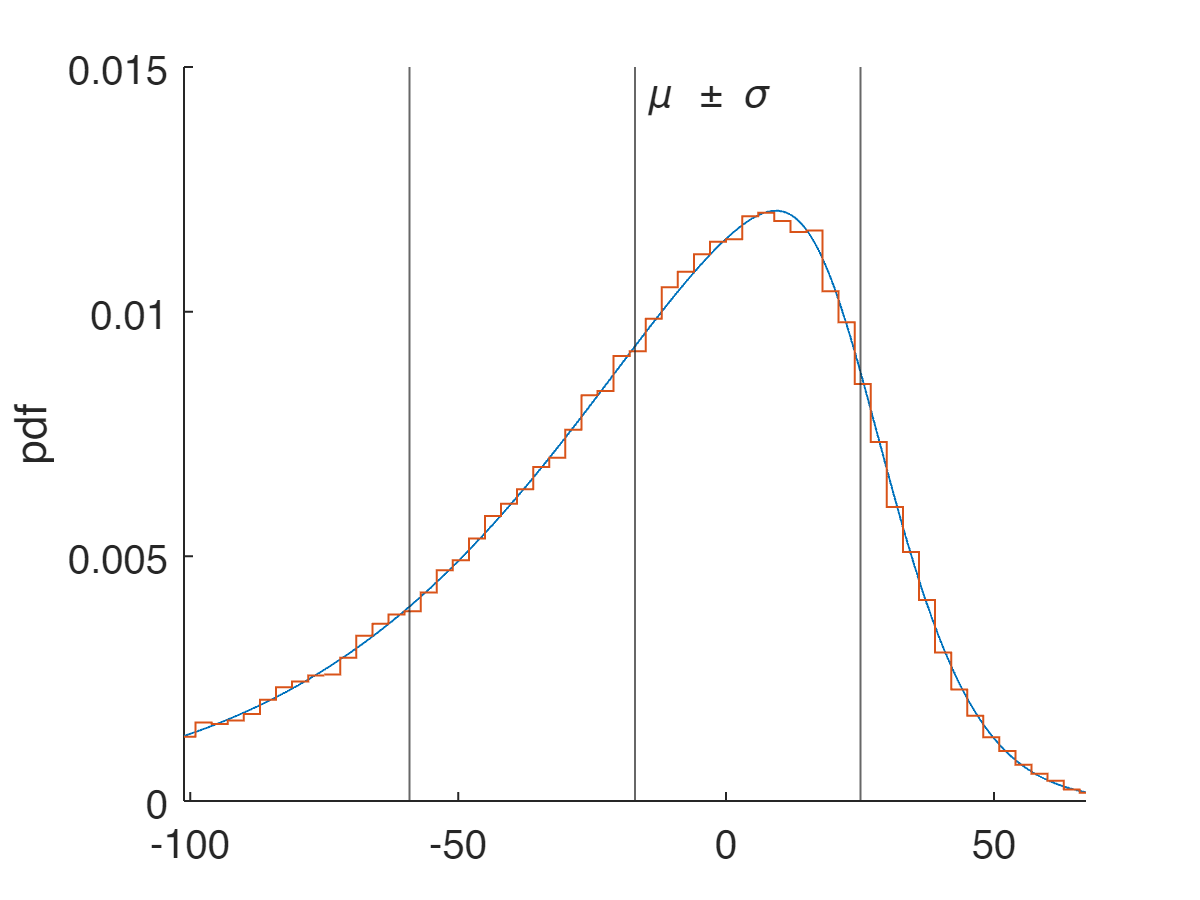

[f,~,x]=gx2pdf('full',w,k,lambda,s,m);
figure;  hold on
plot(x,f)
histogram(r,'normalization','pdf','displaystyle','stairs')
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-2*sqrt(v),mu+2*sqrt(v)]); ylim([0 .015]); ylabel 'pdf'

### Compare calculated and sampled cdf's

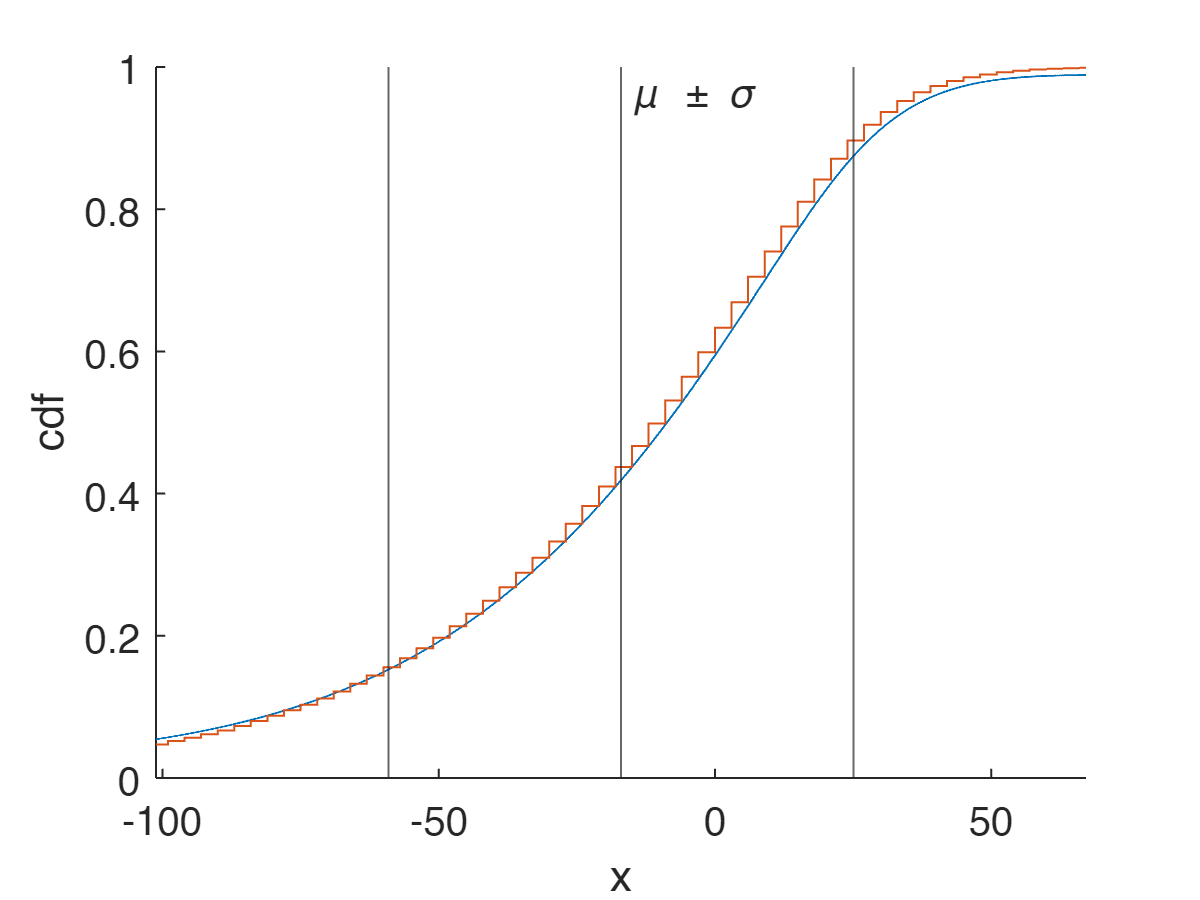

[p,~,x]=gx2cdf('full',w,k,lambda,s,m);
figure; hold on
plot(x,p)
histogram(r,'normalization','cdf','displaystyle','stairs')
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-2*sqrt(v),mu+2*sqrt(v)]); ylim([0 1]); xlabel x; ylabel 'cdf'

## Compute inverse cdf

x=gx2inv([0.5 0.9],w,k,lambda,s,m)

x =   -8.765662415017413  27.532048762926731


Compute quantiles for cdf values of 1e-3 and 1e-2:

x=gx2inv([-3 -2],w,k,lambda,s,m)

x = 1.0e+02 *

  -2.192552733503043  -1.492618191281874


Compute quantiles for complementary cdf values of 1e-3 and 1e-2:

x=gx2inv([-3 -2],w,k,lambda,s,m,'upper')

x =   69.489931056249731  51.033780461417180


## Compute characteristic function

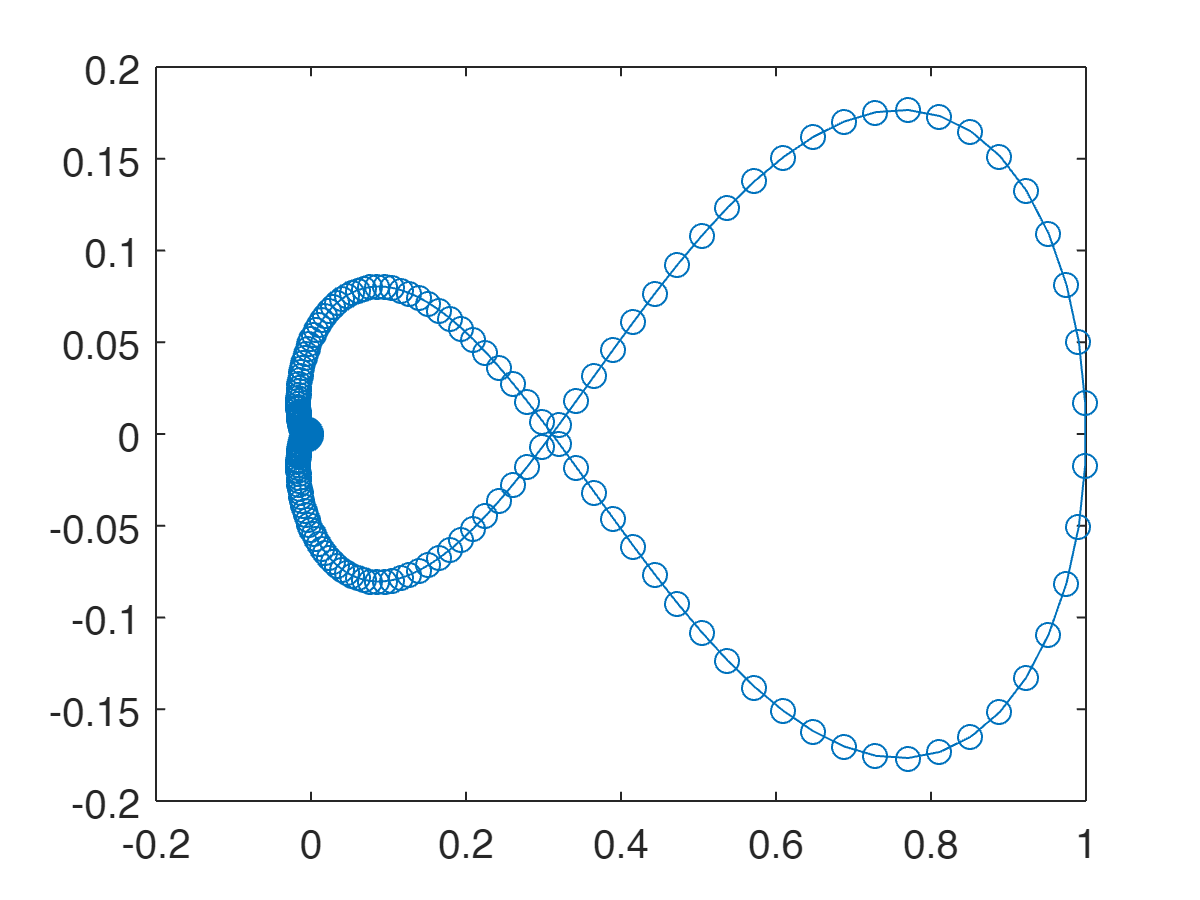

t=linspace(-1,1,1e3);
phi=gx2char(t,w,k,lambda,s,m);
figure; plot(phi,'-o')

## Distribution of quadratic form of a normal variable

Normal parameters:

mu=[5;6]; % mean
v=[2 1; 1 3]; % covariance matrix

Sample normal random vectors:

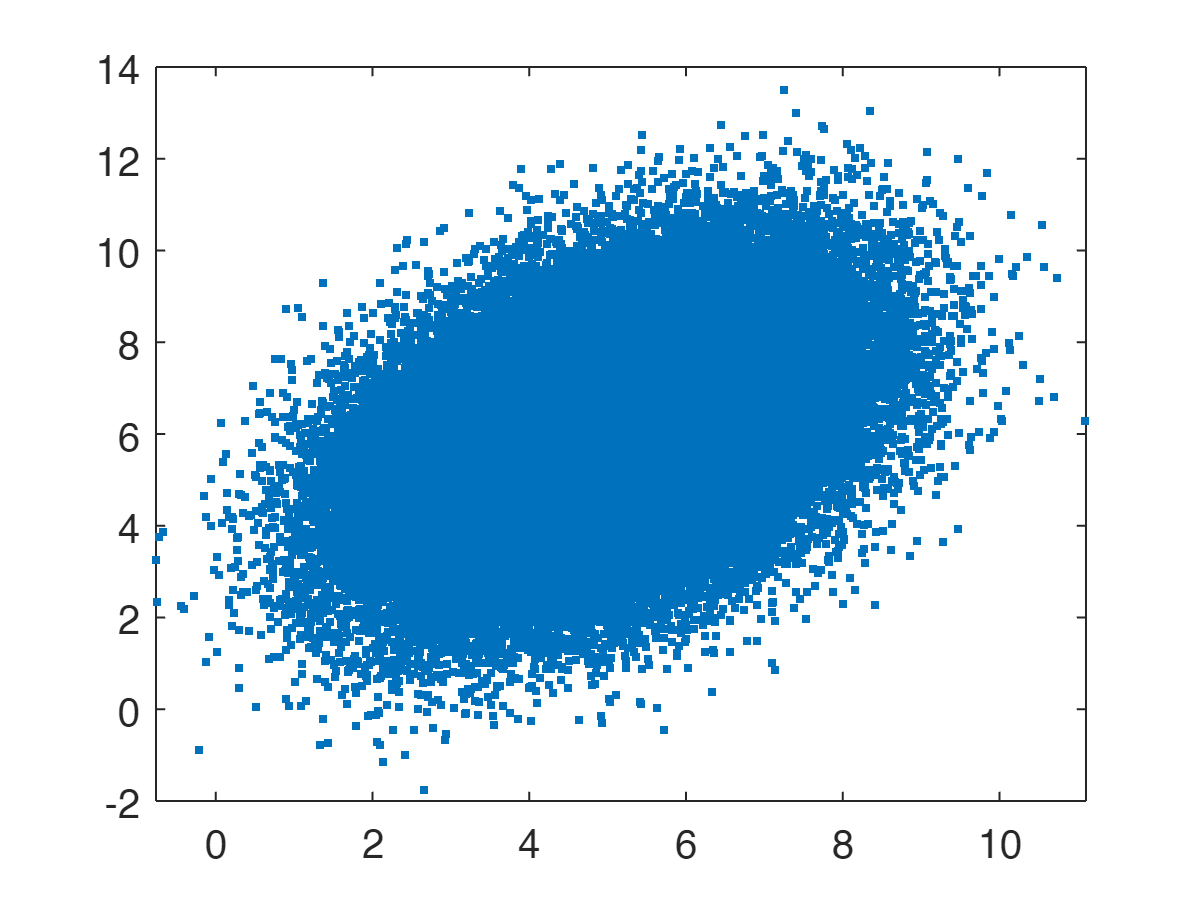

x=mvnrnd(mu,v,1e5)';
figure; plot(x(1,:),x(2,:),'.')

Quadratic form $q(\mathbf{x})=(x_1+x_2)^2-x_1-1$` = [x1;x2]'*[1 1; 1 1]*[x1;x2] + [-1;0]'*[x1;x2] -1`

quad.q2=[1 1; 1 1];
quad.q1=[-1;0];
quad.q0=-1;

Compute the quadratic form *q* for the sample of normal vectors:

q=dot(x,quad.q2*x)+quad.q1'*x+quad.q0;

Get generalized chi-square parameters corresponding to this quadratic form:

[w,k,lambda,s,m]=norm_quad_to_gx2_params(mu,v,quad)

w =    6.999999999999996


k =      1


lambda =   16.618804664723040


s =    0.845154254728509


m =   -1.331632653061220


Compare the sampled and calculated distributions of *q*:

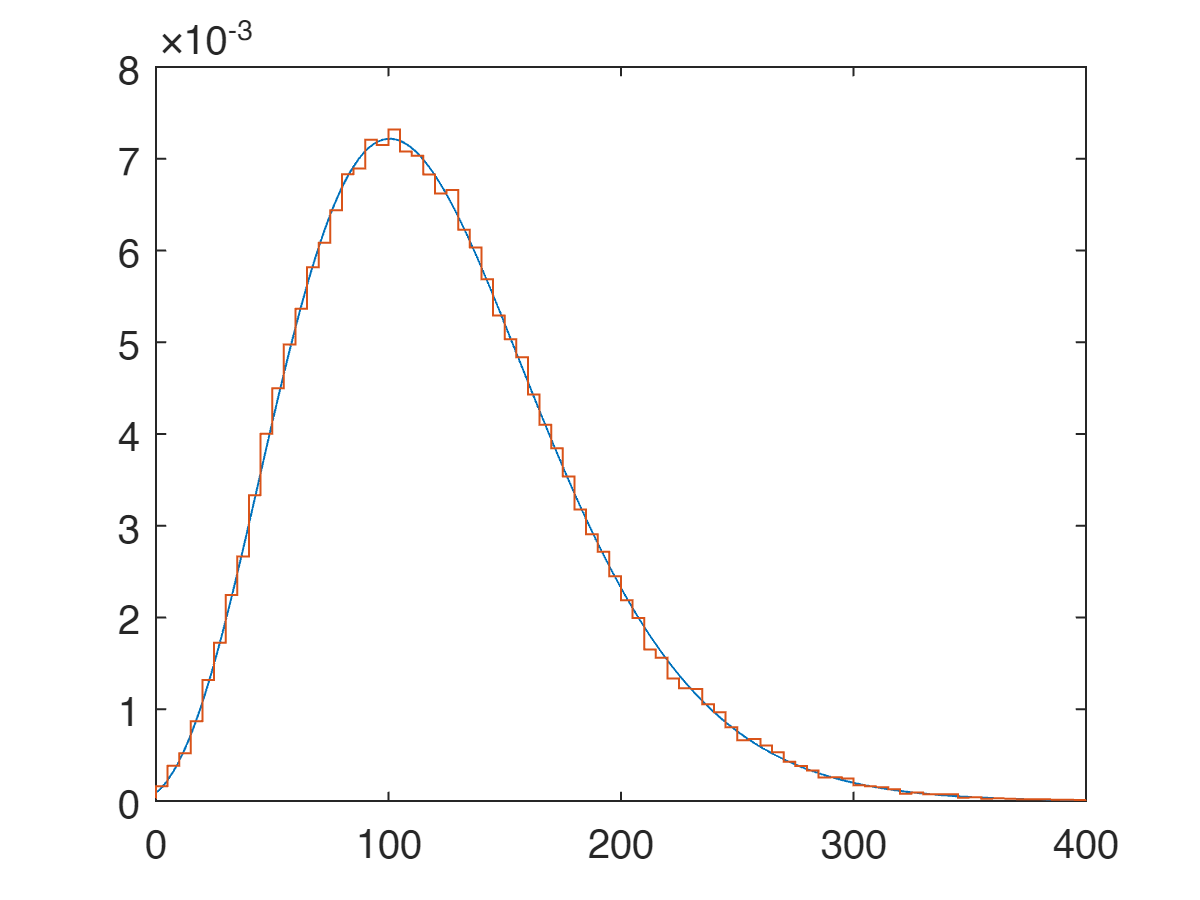

[f,~,x]=gx2pdf('full',w,k,lambda,s,m);
plot(x,f); hold on
histogram(q,'normalization','pdf','displaystyle','stairs')
xlim([0 400])

Compare the sampled and calculated means and variances:

[mu_q,v_q]=gx2stat(w,k,lambda,s,m);
[mu_q mean(q)]

ans = 1.0e+02 *

   1.220000000000000   1.219802665100824


[v_q var(q)]

ans = 1.0e+03 *

   3.355999999999998   3.365060488190333


Compare the sampled and calculated probabilities $p(q(\mathbf{x})<50)$:

mean(q<50)

ans =    0.086260000000000


gx2cdf(50,w,k,lambda,s,m)

ans =    0.085591685953798


Find a canonical quadratic form of a standard multinormal corresponding to these generalized chi-square parameters:

quad=gx2_to_norm_quad_params(w,k,lambda,s,m)

quad = struct with fields:
    q2: [2×2 double]
    q1: [2×1 double]
    q0: 115
